dt=1/1000;
t = 0:dt:0.5;
u1 = sin(2*pi*50*t);
u2 = sin(2*pi*100*t);
u3 = 0*sin(2*pi*75*t);

u = u1+u2+u3;
M=300;
H = hankel(u(1:M),u(M:end));

[U,S,V]=svd(H);

rr=rank(H)

rr = 4

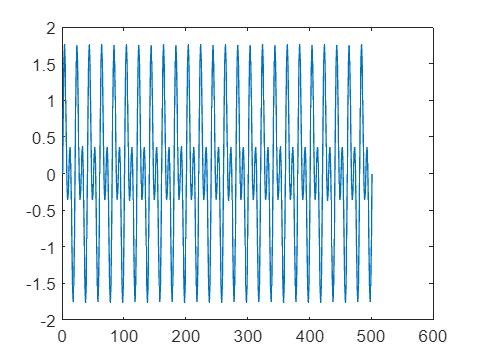

figure; plot(u)

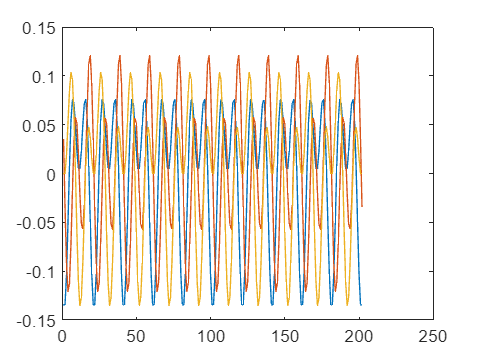


%kunnen we dmv de values van V en die individueel gebruiken om het volgende
%punt te voorspelen mogelijk een betere voorspelling doen dan als we het
%gecombineerde gebruiken om het volgende punt te voorspellen?
figure; plot(V(:,1));
hold all; plot(V(:,2));
plot(V(:,3))